# Part 1: Step 1


snr_db = zeros(1,10);
snr = zeros(1, 10);         
bit_errors = zeros(1, 10);  
block_errors = zeros(1, 10);
symbol_errors = zeros(1, 10)

symbol_errors =      0     0     0     0     0     0     0     0     0     0



for i = 1:10
    snr_db(i) = 4 + i;           
    snr(i) = 10.^(snr_db(i)/10); 
    n_loops = 0;         
    n_symbol_errors = 0; 
    n_bit_errors = 0;    
    n_block_errors = 0;

%step 2
    while n_symbol_errors < 100

        tx_signal = 2 * (rand(100, 1) > 0.5) - 1;
        noise = 1/sqrt(snr(i))*randn(100,1);
        rx_signal = tx_signal+noise;
        rx_decoded = sign(rx_signal);
        cur_n_symbol_errors = sum(rx_decoded ~= tx_signal);
  
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_bit_errors= n_symbol_errors;
        if(cur_n_symbol_errors>0)
            n_block_errors = n_block_errors+1;
        end
        n_loops=n_loops+1;
    end 

% step 3    
    symbol_errors(i)=n_symbol_errors/(n_loops*100);
    disp(i);
    bit_errors(i)=n_bit_errors/(n_loops*100);
    disp(i);
    block_errors(i)=n_block_errors/n_loops;
    disp(i);
end

     1



     1



     1



     2



     2



     2



     3



     3



     3



     4



     4



     4



     5



     5



     5



     6



     6



     6



     7



     7



     7



     8



     8



     8



     9



     9



     9



    10



    10



    10



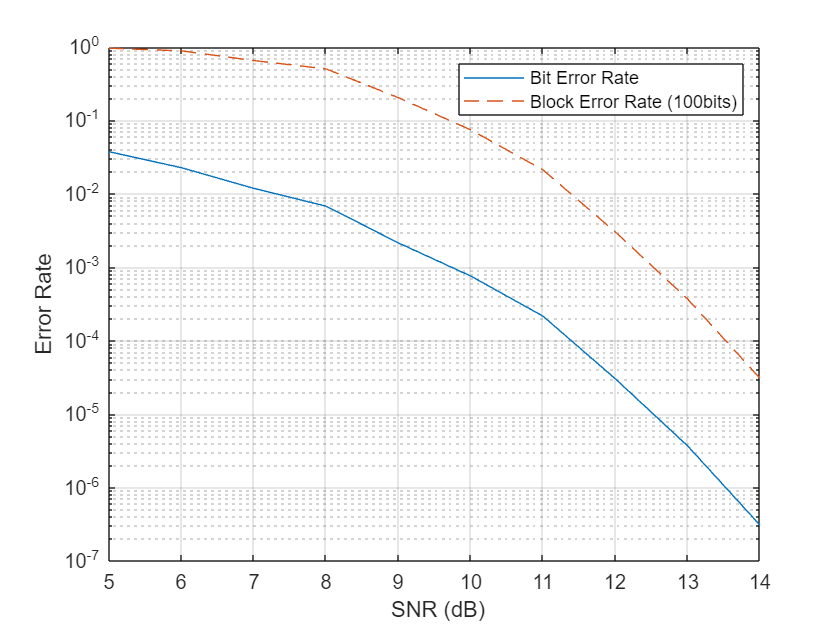


semilogy(snr_db,bit_errors,snr_db,block_errors,'--');
legend('Bit Error Rate','Block Error Rate (100bits)') 
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid


% disp(i) just show the position of for loop
% block error is much higher than symbol error because we didn't devide
% n_block_errors by loops*100, other devide by 100 because bit rate



## Part 2


snr_db = zeros(1,10);
snr = zeros(1, 10);         
bit_errors = zeros(1, 10);  
block_errors = zeros(1, 10);
symbol_errors = zeros(1, 10);
% Initialize arrays for real and imaginary error counts
real_errors = zeros(1, 10);
imag_errors = zeros(1, 10);

for i = 1:10
    snr_db(i) = 4 + i;           
    snr(i) = 10.^(snr_db(i)/10); 
    n_loops = 0;         
    n_symbol_errors = 0; 
    n_bit_errors = 0;    
    n_block_errors = 0;
    n_real_errors=0;
    n_imag_errors=0;
%step 2
    while n_symbol_errors < 100

        tx_signal = 3*(rand(100, 1))+1;
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));
        rx_signal = tx_signal+noise;
        
        decode_real = sign(real(rx_signal));
        decode_imag = sign(imag(rx_signal));
        
        real_part_errors = decode_real ~= real(tx_signal);
        imag_part_errors = decode_imag ~= imag(tx_signal);
        
        n_real_errors = n_real_errors + sum(real_part_errors);
        n_imag_errors = n_imag_errors + sum(imag_part_errors);
        cur_n_symbol_errors = sum(n_real_errors | n_imag_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops=n_loops+1;
    end 

% step 3    
    
    symbol_errors(i)=n_symbol_errors/(n_loops*200);
    disp(i);
    bit_errors(i)=n_bit_errors/(n_loops*200);
    disp(i);
    block_errors(i)=n_block_errors/n_loops;
    disp(i);
end

     1



     1



     1



     2



     2



     2



     3



     3



     3



     4



     4



     4



     5



     5



     5



     6



     6



     6



     7



     7



     7



     8



     8



     8



     9



     9



     9



    10



    10



    10



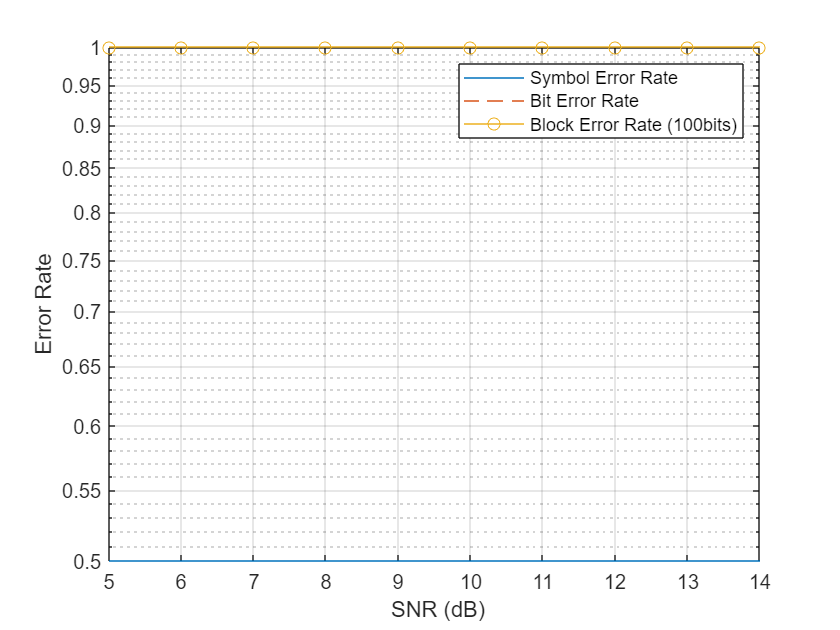


semilogy(snr_db,symbol_errors,snr_db,bit_errors,'--',snr_db,block_errors,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100bits)');
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid

  
snr_db = zeros(1, 10);              % SNR values in dB
snr = zeros(1, 10);                 % Linear SNR values
bit_errors = zeros(1, 10);          % Bit error counts
block_errors = zeros(1, 10);        % Block error counts
symbol_errors = zeros(1, 10);       % Symbol error counts
real_errors = zeros(1, 10);         % Real part errors
imag_errors = zeros(1, 10);         % Imaginary part errors
QPSK = [1+1j, 1-1j, -1+1j, -1-1j];

for i = 1:10
    snr_db(i) = 4 + i;
    snr(i) = 10.^(snr_db(i)/10);
    n_loops = 0;
    n_symbol_errors = 0;
    n_bit_errors = 0;
    n_block_errors = 0;
    n_real_errors = 0;
    n_imag_errors = 0;

    while n_symbol_errors < 100
        tx_indices = randi([1, 4], 100, 1);  % Random indices for QPSK symbols
        tx_signal = QPSK(tx_indices);       % Transmit QPSK symbols
        noise = 1/sqrt(2*snr(i)) * ((randn(100, 1) + 1j*randn(100, 1)));
        rx_signal = tx_signal + noise;

        decode_real = sign(real(rx_signal));
        decode_imag = sign(imag(rx_signal));

        real_part_errors = decode_real ~= real(tx_signal);
        imag_part_errors = decode_imag ~= imag(tx_signal);

        n_real_errors = n_real_errors + sum(real_part_errors);
        n_imag_errors = n_imag_errors + sum(imag_part_errors);

        cur_n_symbol_errors = sum(real_errors | imag_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops = n_loops + 1;
    end

    symbol_errors(i) = n_symbol_errors / (n_loops * 100);
    bit_errors(i) = (n_real_errors + n_imag_errors) / (n_loops * 200);  % Each symbol error affects two bits in QPSK
    block_errors(i) = n_block_errors / n_loops;

    disp(['SNR: ', num2str(snr_db(i)), ' dB']);
    disp(['Symbol Error Rate: ', num2str(symbol_errors(i))]);
    disp(['Bit Error Rate: ', num2str(bit_errors(i))]);
    disp(['Block Error Rate: ', num2str(block_errors(i))]);
end

semilogy(snr_db,symbol_errors,snr_db,bit_errors,'--',snr_db,block_errors,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100bits)');
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid

frame_time = zeros(1, 100)

frame_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:100
    frame_time(i) = 5e-3;
end
n_echoes = 1;
f_doppler = (0.3*2000/3.8e10);
snr_a_db = zeros(1,10);
snr_a = 0;
